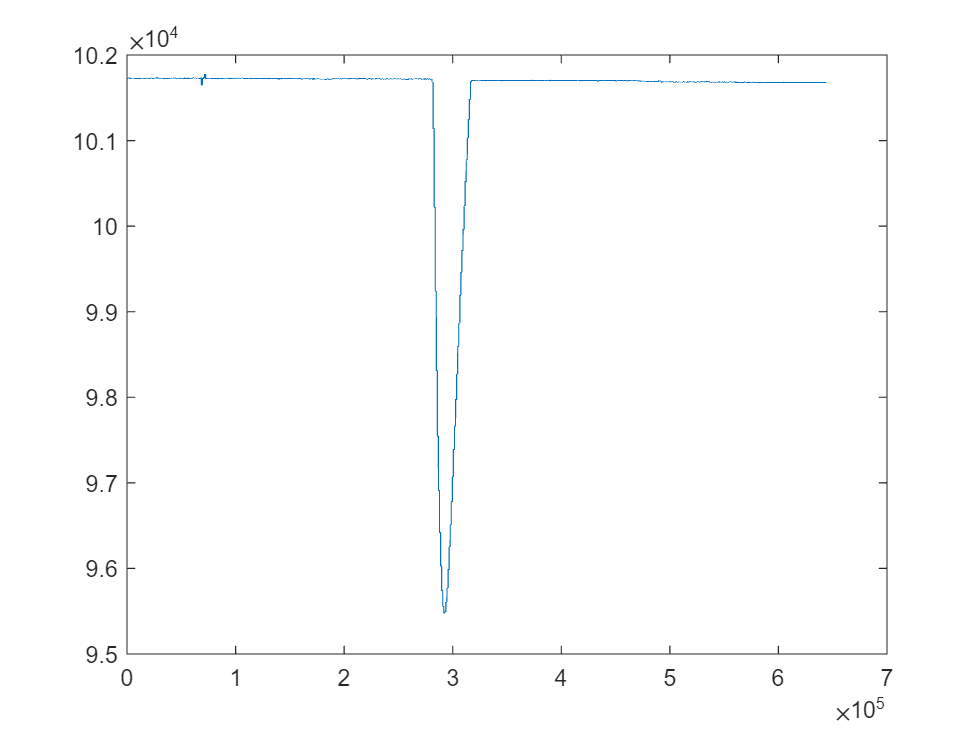

clear 

warning('off', 'all')
% Variables 

% Importing data into an array 
data = readmatrix("astra2_full_testdata.txt");
figure
plot(data(:, 1)-data(1,1), data(:, 2))

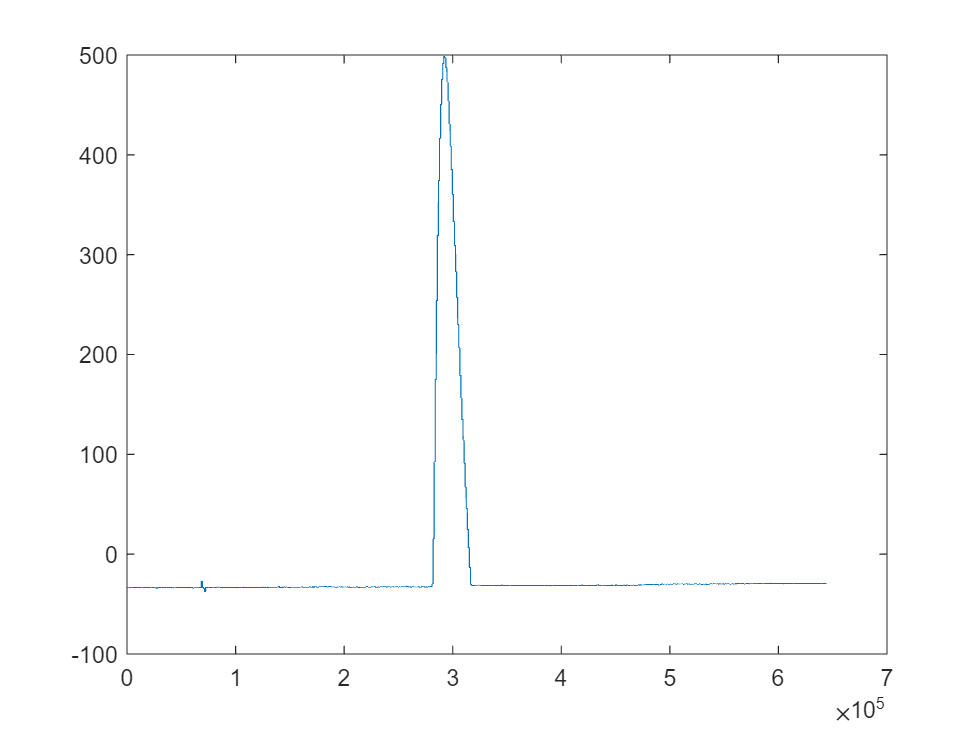

figure
plot(data(:, 1)-data(1,1), atmospalt(data(:, 2)))


alldata = []; % empty array of all data - will be filled up later on.
launchData = []; % the first value of this array is defined as the initlaunchtime. 

% Variables
refpressure = 101728.25;
maxthrustaltitude = 220;
ag1 = 300; % Apogee guess 1.
ag2 = 350; % Apogee guess 2.
min_triggeralt = 10;

for i = 1:length(data) % Taking in data point by point - to mimic the pressure readings. 
    alldata(i,1) = data(i,1); % Adding each time datapoint onto the end of all data array. 
    alldata(i,2) = data(i,2); % pressure point.
    alldata(i,3) = 44330 * ( 1 - (alldata(i,2)/refpressure)^(1/5.255)); % calculating the altitude at each pressure point. 
%     alldata(i, 3) = atmospalt(alldata(i, 2));

    currentt = alldata(i,1);
    currentalt = alldata(i,3);
    % checking if the altitude is above 10m. 
    if alldata(i,3) > min_triggeralt
        
       
        % checking if the max thrust altitude has been reached.
        % the time at which this happens is called MTAT.
        % Index for that time is called MTI.
        if alldata(i,3) > maxthrustaltitude
            MTI = find(launchData(:,2)>maxthrustaltitude,1);
            MTAT = launchData(MTI,1);
            
            if length(launchData(MTI:end,1)) < 3
                continue
            end

%             while (ag2 - ag1) > 10
%                 ag1 = ag2 ;
                Ts = launchData(MTI:end,1) - launchData(1,1);
                As = launchData(MTI:end,2);
%                
%                 % Matrix multiplication. 
% %                 y = ([sum(Ts.^4), sum(Ts.^3), sum(Ts.^2); sum(Ts.^3), sum(Ts.^2), sum(Ts.^1); sum(Ts.^2), sum(Ts), 1]);
% %                 z = [sum(As.*(Ts.^3)); sum(As.*(Ts.^2)); sum(As.*Ts)];                
% %                 result = (y.^-1) * z;
% 
%                 y = ([1, sum(Ts), sum(Ts.^2); sum(Ts.^1), sum(Ts.^2), sum(Ts.^3); sum(Ts.^2), sum(Ts.^3), sum(Ts.^4)]);
%                 z = [sum(As.*(Ts.^1)); sum(As.*(Ts.^2)); sum(As.*(Ts.^3))];
%                 %z = [sum(As); sum(As.*(Ts)); sum(As.*Ts.^2)];                
% %                 result = inv(y) * z;
%                 result = y\z;
% 
%                 diff = polyder(result);
%                 tguess = -diff(2)/(diff(1));
%                 ag2 = polyval(result,tguess);
%             end 

%             A = [(launchData(MTI:end,1) - launchData(1,1)).^2, (launchData(MTI:end,1) - launchData(1,1)), ones(length(launchData(MTI:end,1)), 1)];
%             y = launchData(MTI:end,2);

%             Matrix multiplication. 
            y = ([sum(Ts.^4), sum(Ts.^3), sum(Ts.^2); sum(Ts.^3), sum(Ts.^2), sum(Ts.^1); sum(Ts.^2), sum(Ts), length(Ts)]);
            z = [sum(As.*(Ts.^2)); sum(As.*(Ts.^1)); sum(As)];                
            coeffs = y\z;
            velcoeffs = [2*coeffs(1); coeffs(2)];
            
            if As(end) == As(end-1)
                continue
            end
            ag1 = ag2;
            tguess = -velcoeffs(2)/velcoeffs(1);
            ag2 = coeffs(1)*tguess^2 + coeffs(2)*tguess + coeffs(3);

            
            if ag2 - ag1 < 1 && launchData(end, 2) <= ag2
                vel = velcoeffs(1)*Ts(end) + velcoeffs(2);
                sprintf('Apogee detected at t = %.1f, alt = %.1f, v = %.2f', Ts(end)/1000, As(end), vel)
            end
        end 

    end
end

ans = 'Apogee detected at t = 7.8, alt = 508.9, v = 0.03'

ans = 'Apogee detected at t = 8.9, alt = 524.6, v = 0.02'

ans = 'Apogee detected at t = 9.8, alt = 531.6, v = 0.01'

ans = 'Apogee detected at t = 10.8, alt = 530.4, v = -0.00'

ans = 'Apogee detected at t = 11.8, alt = 520.6, v = -0.01'

ans = 'Apogee detected at t = 12.8, alt = 506.2, v = -0.02'

ans = 'Apogee detected at t = 13.8, alt = 487.2, v = -0.03'

ans = 'Apogee detected at t = 14.7, alt = 464.1, v = -0.03'

ans = 'Apogee detected at t = 15.7, alt = 441.9, v = -0.04'

ans = 'Apogee detected at t = 16.7, alt = 418.5, v = -0.04'

ans = 'Apogee detected at t = 17.7, alt = 393.6, v = -0.05'

ans = 'Apogee detected at t = 18.7, alt = 366.1, v = -0.05'

ans = 'Apogee detected at t = 19.7, alt = 342.6, v = -0.05'

ans = 'Apogee detected at t = 20.7, alt = 316.1, v = -0.05'

ans = 'Apogee detected at t = 21.6, alt = 290.7, v = -0.05'

ans = 'Apogee detected at t = 22.6, alt = 263.2, v = -0.05'

ans = 'Apogee detected at t = 23.6, alt = 240.0, v = -0.05'


% Functions. 
